clear all
load("parameters.mat")

setting initial conditions

x0 =[0,pi/18,0,0]';


Observer filters

fc=0.1; %cutoff frequency
Tc = 1/(2*pi*fc); 


M matrix coefficients

num1.m11 = 2*wheel.Iyy+2*gbox.N^2*mot.rot.Iyy+ (body.m+2*wheel.m+2*mot.rot.m)*wheel.r^2;
num1.m12 = 2*gbox.N*(1-gbox.N)*mot.rot.Iyy;
num1.k = (body.m*body.zb+2*mot.rot.m*mot.rot.zb)*wheel.r;
num1.m22 = body.Iyy+2*((1-gbox.N)^(2))*mot.rot.Iyy+body.m*(body.zb^2)+2*mot.rot.m*(mot.rot.zb)^2;


C matrix coefficients

num1.c12 = -(body.m*body.zb+2*mot.rot.m*mot.rot.zb)*wheel.r;


define Fv'

num1.Fv11 = 2*(gbox.B+wheel.B);
num1.Fv12 = -2*gbox.B;
num1.Fv22 = 2*gbox.B;
num1.j = 2*gbox.N^2*mot.Kt*mot.Ke/mot.R;

num1.f11 = num1.Fv11 + num1.j; 
num1.f21 = num1.Fv12 - num1.j; 
num1.f22 = num1.Fv22 + num1.j; 


Define G

num1.g2 = -(body.m*body.zb+2*mot.rot.m*mot.rot.zb)*g;


define Inputs matrix

num1.j_tau = 2*gbox.N*mot.Kt/mot.R;
disp(num1)

      m11: 0.0174
      m12: -0.0153
        k: 0.0016
      m22: 0.0193
      c12: -0.0016
     Fv11: 0.0530
     Fv12: -0.0500
     Fv22: 0.0500
        j: 0.0398
      f11: 0.0928
      f21: -0.0898
      f22: 0.0898
       g2: -0.4665
    j_tau: 0.1294



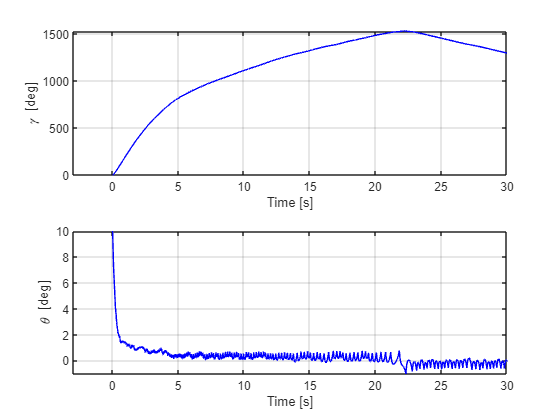

%unstable sliding mode
load("sliding_sing_5.mat")
figure()
subplot(2,1,1)
plot(out.gamma.time,out.gamma.signals.values,'-b')
grid on
ylabel('\gamma [deg]')
xlabel ('Time [s]')
xlim([-3,30])
subplot(2,1,2)
plot(out.theta.time,out.theta.signals.values,'-b')
grid on
ylabel('\theta [deg]')
xlabel ('Time [s]')
xlim([-3,30])

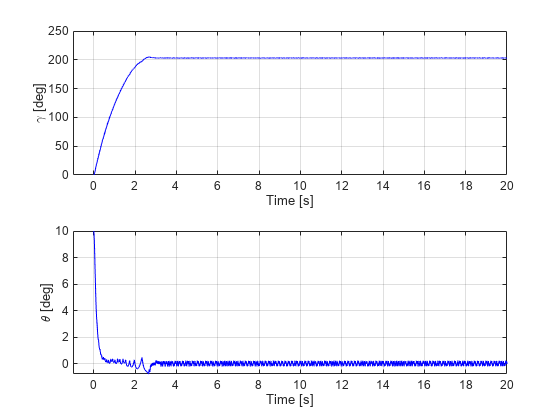

%stabilizable sliding mode
load("sliding_sing_10.mat")
figure()
subplot(2,1,1)
plot(out.gamma.time,out.gamma.signals.values,'-b')
grid on
ylabel('\gamma [deg]')
xlabel ('Time [s]')
xlim([-1,20])
subplot(2,1,2)
plot(out.theta.time,out.theta.signals.values,'-b')
grid on
ylabel('\theta [deg]')
xlabel ('Time [s]')
xlim([-1,20])

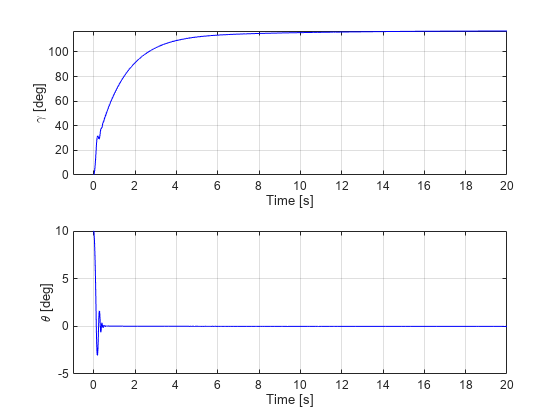


% sliding mode with saturation
load("sliding_sat_100_1.mat")
figure()
subplot(2,1,1)
plot(out.gamma.time,out.gamma.signals.values,'-b')
grid on
ylabel('\gamma [deg]')
xlabel ('Time [s]')
xlim([-1,20])
subplot(2,1,2)
plot(out.theta.time,out.theta.signals.values,'-b')
grid on
ylabel('\theta [deg]')
xlabel ('Time [s]')
xlim([-1,20])

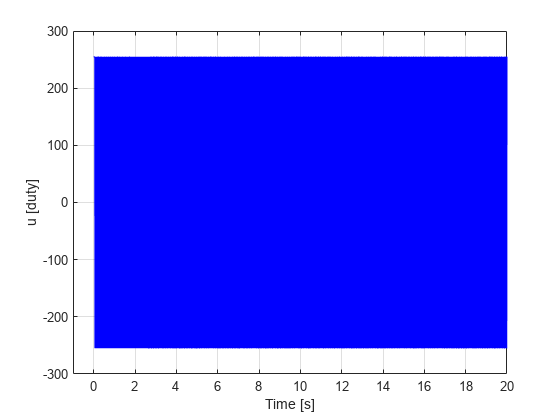

%control Actions sign
load("sliding_sing_10.mat")
figure()
plot(out.gamma.time,out.u_sat.signals.values,'-b')
grid on
ylabel('u [duty]')
xlabel ('Time [s]')
xlim([-1,20])

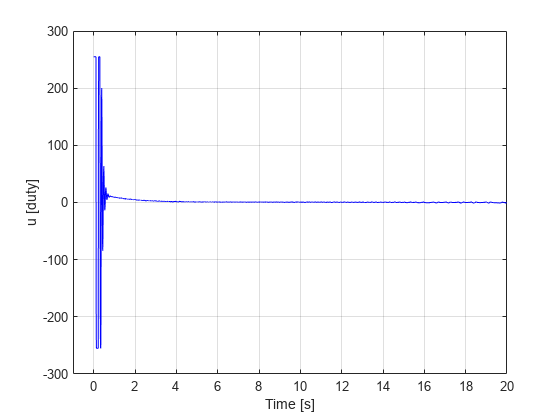

%control action saturation
figure()
load("sliding_sat_100_1.mat")
plot(out.theta.time,out.u_sat.signals.values,'-b')
grid on
ylabel('u [duty]')
xlabel ('Time [s]')
xlim([-1,20])

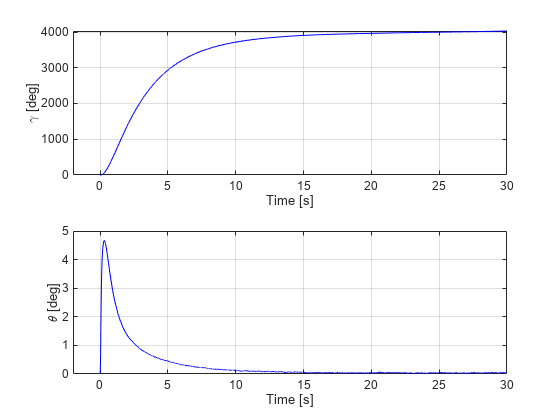

load("fb_base.mat")
figure()
subplot(2,1,1)
plot(out.gamma.time,out.gamma.signals.values,'-b')
grid on
ylabel('\gamma [deg]')
xlabel ('Time [s]')
xlim([-2,30])
subplot(2,1,2)
plot(out.theta.time,out.theta.signals.values,'-b')
grid on
ylabel('\theta [deg]')
xlabel ('Time [s]')
xlim([-2,30])

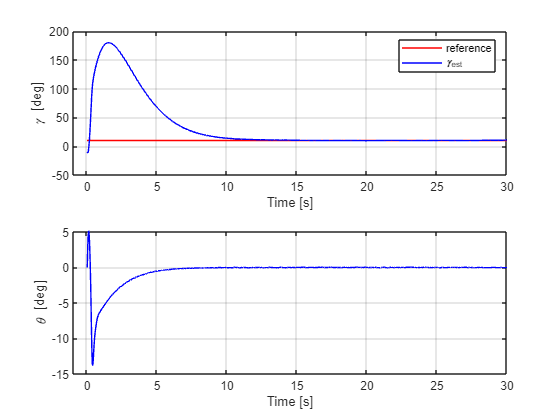


load("fb_stable_no_dist.mat")
figure()
subplot(2,1,1)
plot(0:50:50,[10, 10],'-r')
hold on
plot(out.gamma.time,out.gamma.signals.values,'-b')
grid on
ylabel('\gamma [deg]')
xlabel ('Time [s]')
legend('reference','\gamma_{est}')
xlim([-1,30])
subplot(2,1,2)
plot(out.theta.time,out.theta.signals.values,'-b')
grid on
ylabel('\theta [deg]')
xlabel ('Time [s]')
xlim([-1,30])

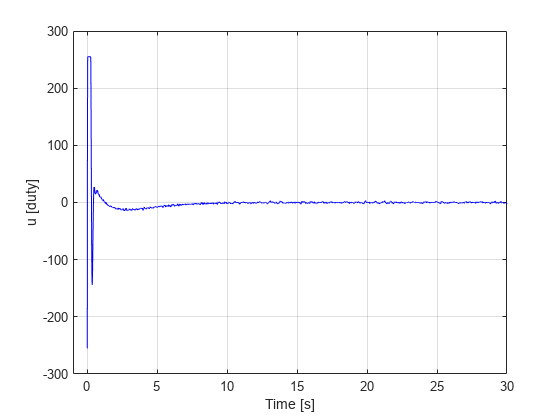

figure()

plot(out.u_sat.time,out.u_sat.signals.values,'-b')
grid on
ylabel('u [duty]')
xlabel ('Time [s]')
xlim([-1,30])

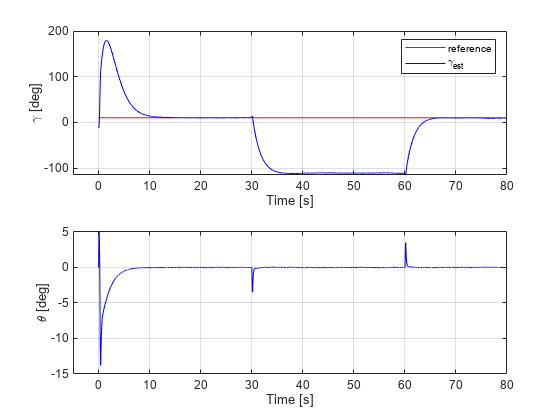




load("fb_stable_dist.mat")
figure()
subplot(2,1,1)
plot(0:100:100,[10, 10],'-r')
hold on
plot(out.gamma.time,out.gamma.signals.values,'-b')
grid on
ylabel('\gamma [deg]')
xlabel ('Time [s]')
legend('reference','\gamma_{est}')
xlim([-5,80])
subplot(2,1,2)
plot(out.theta.time,out.theta.signals.values,'-b')
grid on
ylabel('\theta [deg]')
xlabel ('Time [s]')
xlim([-5,80])